clc; clear; close all

IMU_Rev2_Data_Short = importdata("IMU_Rev2_Data_Short.txt")

IMU_Rev2_Data_Short = 1.0e+04 *

                   0   0.000010527504387  -0.000000957045853   0.000999155870909   0.000115205615320  -0.000088502327001   0.000149538414588   0.809600000000000   0.809600000000000                   0                   0   0.009749615625000   0.003415761184692
   0.000005000000000   0.000012441596094   0.000005742275120   0.000997241779202  -0.000065613794156   0.000046540016785   0.000410467689021   0.809600000000000   0.809600000000000                   0                   0   0.009749864843750   0.003416206359863
   0.000010000000000   0.000021533531701   0.000005263752193   0.000998198825055  -0.000012970168612   0.000001525902190   0.000254062714580   0.809600000000000   0.809600000000000                   0                   0   0.009749864843750   0.003416206359863
   0.000015000000000   0.000013398641947  -0.000000478522927   0.000995806210422  -0.000015259021897                   0   0.000066376745251   0.809600000000000   0.809600000000000    

IMU_Rev2_Data_Long = importdata("IMU_Rev2_Data_Long.txt")

IMU_Rev2_Data_Long = 1.0e+04 *

                   0   0.000013398641947   0.000011484550240   0.000994370641642   0.000158693827726   0.000009155413138  -0.000003814755474   0.809600000000000   0.816000000000000                   0                   0   0.009750079687500   0.003398398208618
   0.000005000000000   0.000013398641947   0.000002392614633   0.000997720302129  -0.000015259021897   0.000001525902190  -0.000099183642329   0.812800000000000   0.816000000000000                   0                   0   0.009749939843750   0.003397507858276
   0.000010000000000   0.000011963073167  -0.000004306706340   0.001000112916762  -0.000029755092699                   0  -0.000073243305104   0.812800000000000   0.816000000000000                   0                   0   0.009750087500000   0.003397953414917
   0.000015000000000   0.000014355687800  -0.000003828183413   0.000998677347982  -0.000041962310216   0.000000762951095  -0.000029755092699   0.812800000000000   0.816000000000000     


% x red
% y green
% z blue

Figure 1: Raw Data without Rig

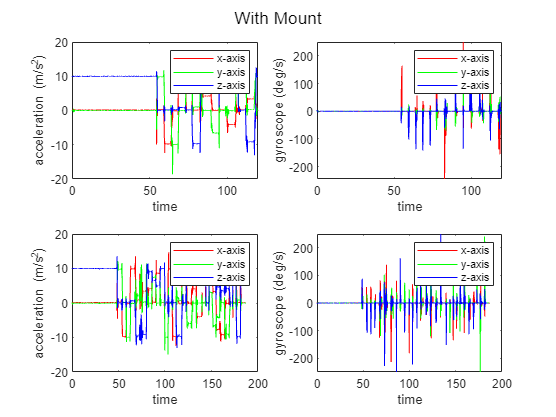

figure
subplot(2,2,3)
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,2),'r')
hold on
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,3),'g')
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,4),'b')
xlabel('time');ylabel('acceleration (m/s^2)')
legend('x-axis','y-axis','z-axis')

subplot(2,2,4)
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,5),'r')
hold on
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,6),'g')
plot(IMU_Rev2_Data_Long(:,1),IMU_Rev2_Data_Long(:,7),'b')
xlabel('time');ylabel('gyroscope (deg/s)')
legend('x-axis','y-axis','z-axis')

% figure('Name','Computed Data - With Mount')
subplot(2,2,1)
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,2),'r')
hold on
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,3),'g')
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,4),'b')
xlabel('time');ylabel('acceleration (m/s^2)')
legend('x-axis','y-axis','z-axis')

subplot(2,2,2)
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,5),'r')
hold on
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,6),'g')
plot(IMU_Rev2_Data_Short(:,1),IMU_Rev2_Data_Short(:,7),'b')
xlabel('time');ylabel('gyroscope (deg/s)')
legend('x-axis','y-axis','z-axis')

sgtitle('With Mount')